# Classical Pendulum: Some Algorithm-Related Issues

This example shows how the estimation algorithm choices may impact the results for a nonlinear grey box model estimation. We use data produced by a nonlinear pendulum system, which is schematically shown in Figure 1. We show in particular how the choice of differential equation solver impacts the results.

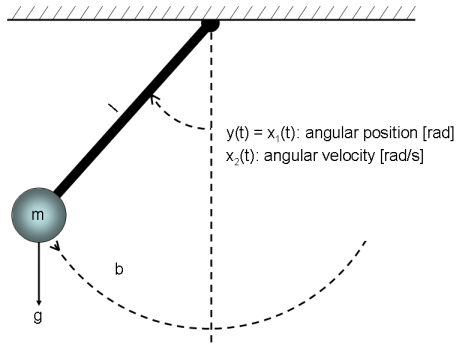

**Figure 1:** Schematic view of a classical pendulum.

## Output Data

We start our modeling tour by loading the output data (time-series data). The data contains one output, y, which is the angular position of the pendulum [rad]. The angle is zero when the pendulum is pointing downwards, and it is increasing anticlockwise. There are 1001 (simulated) samples of data points and the sample time is 0.1 seconds. The pendulum is affected by a constant gravity force, but no other exogenous force affects the motion of the pendulum. To investigate this situation, we create an IDDATA object:

loadSim

Loading file: D06_05_h05_Ea_An00H00_R01
Loading file: D06_05_h05_Eb_An00H00_R01
Loading file: D06_05_h05_Ef_Ab05H02_R01
Loading file: D06_05_h05_Ef_Ab05H05_R01
Loading file: D06_05_h05_Ef_Ac05H0108_R01
Loading file: D06_05_h05_Ef_Ac08H0108_R01
Loading file: D06_05_h05_Ef_As03H02_R01
Loading file: D06_05_h05_Ef_As03H05_R01
Loading file: D06_05_h05_Ef_As03H10_R01
Loading file: D06_05_h05_Ef_As05H05_R01
Loading file: D06_05_h05_Ef_As07H02_R01
Loading file: D06_05_h05_Ef_As10H05_R01
Elapsed time is 0.080819 seconds.
Data loaded


y = D06_05_h05_Ef_As10H05_R01.data(:,2:3);
u = D06_05_h05_Ef_As10H05_R01.data(:,5);
z = iddata(y, u, 0.05, 'Name', 'Pendulum');
z.OutputName = {'Pendulum position','Flywheel angular velocity'};
z.OutputUnit = {'rad','rad/s'};
z.InputName = {'Control Signal'};
z.Tstart = 0;
z.TimeUnit = 's';

FileName      = 'flywheel_m';        % File describing the model structure.
Order         = [2 1 3];             % Model orders [ny nu nx].
Parameters    = [9.81; 0.209; 0.18; 0.492; 0.05; 2.3e-4; 0.029; 0.027; 0.025];   % Initial parameters. %g,Mf,lf,mp,lp,Jf,Jm,c_u,c_v
InitialStates = [0; 0; 0];              % Initial initial states.
Ts            = 0;                   % Time-continuous system.
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts);
nlgr.OutputName = {'Pendulum position','Flywheel angular velocity'};
nlgr.OutputUnit = {'rad','rad/s'};
nlgr.TimeUnit = 's';
nlgr = setinit(nlgr, 'Name', {'Pendulum position' 'Pendulum velocity' 'Flywheel velocity'});
nlgr = setinit(nlgr, 'Unit', {'rad' 'rad/s' 'rad/s'});
nlgr = setpar(nlgr, 'Name', {'Gravity constant' 'Flywheel mass' ...
                      'flywheel length' 'pendulum mass' 'pendulum cog length' 'flywheel inertia' 'pendulum inertia' 'motor torque constant' 'back emf constant'});
nlgr = setpar(nlgr, 'Unit', {'m/s^2' 'kg' 'm' 'kg' 'm' 'inertia' 'inertia' 'idk' 'idk'});
nlgr = setpar(nlgr, 'Minimum', {eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0)});   % All parameters > 0.
nlgr = setpar(nlgr, 'Maximum', {20 2 0.5 3 0.5 inf inf 1 1});   % All parameters > 0.

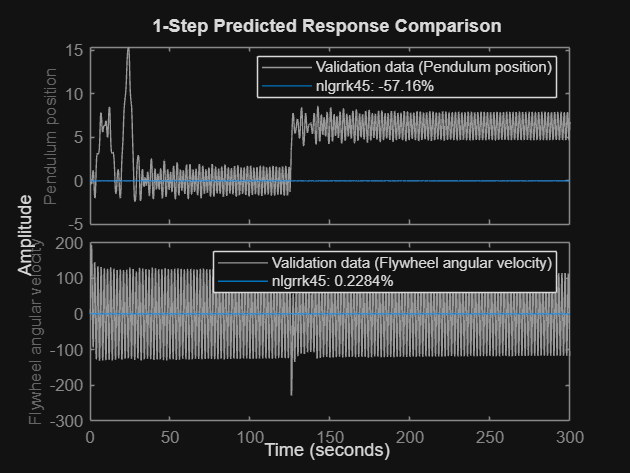


% C. Model computed with adaptive Runge-Kutta 45 ODE solver.
nlgrrk45 = nlgr;
nlgrrk45.SimulationOptions.Solver = 'ode45';     % Runge-Kutta 45.

compare(z, nlgrrk45, 1, ...
   compareOptions('InitialCondition', 'model'));

**Figure 3:** Comparison between true output and the simulated outputs of the three initial pendulum models.

As can be seen, the result with the Euler forward method (with a finer grid than what is used by default) differs significantly from the results obtained with the Runge-Kutta solvers. In this case, it turns out that the Euler forward solver produces a rather good result (in terms of model fit), whereas the outputs obtained with the Runge-Kutta solvers are a bit limited. However, this is somewhat deceiving, as will be evident later on, because the initial value of b, the viscous friction coefficient, is twice as large as in reality.

## Parameter Estimation

The gravitational constant, g, the length of the rod, l, and the mass of the bob, m, can easily be measured or taken from a table without estimation. However, this is typically not the case with friction coefficients, which often must be estimated. We therefore fix the former three parameters to g = 9.81, l = 1, and m = 1, and consider only b as a free parameter:

nlgrrk45 = setpar(nlgrrk45, 'Fixed', {true false false false false false false false false});

We finally use the Runge-Kutta 45 solver (ode45).

opt = nlgreyestOptions('Display', 'on');
trk45 = clock;
nlgrrk45 = nlgreyest(z, nlgrrk45, opt);   % Perform parameter estimation.
trk45 = etime(clock, trk45);

## Performance of Three Estimated Pendulum Models

The results when using these three solvers are summarized below. The true value of b is 0.1, which is obtained with ode45. ode23 returns a value quite close to 0.1, while ode1 returns a value quite a distance from 0.1.

disp('           Estimation time   Estimated b value');

           Estimation time   Estimated b value


fprintf('   ode45:  %3.1f               %1.3f\n', trk45, nlgrrk45.Parameters(3).Value);

   ode45:  129.5               0.254


However, this does not mean that the simulated outputs differ that much from the actual output, because the errors produced by the different differential equation solvers are typically accounted for in the estimation procedure. This is a fact that readily can be seen by simulating the three estimated pendulum models.

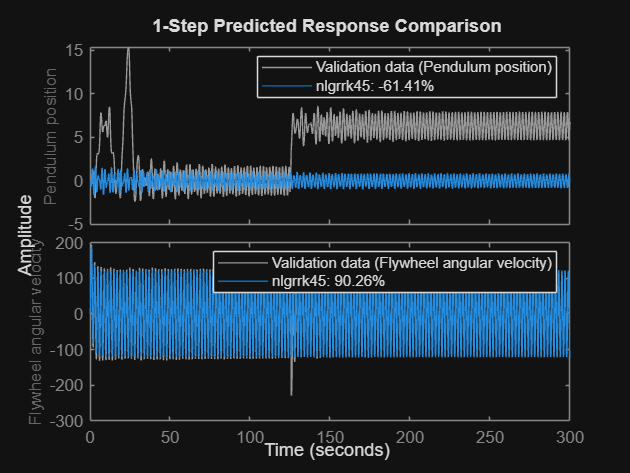

compare(z, nlgrrk45, 1, ...
   compareOptions('InitialCondition', 'model'));

**Figure 4:** Comparison between true output and the simulated outputs of the three estimated pendulum models.

As expected given this figure, the Final Prediction Error (FPE) criterion values of these models are also rather close to each other:

fpe(nlgrrk45);

   1.9932e+03



nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_m' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p9)
    y(t) = H(t, u(t), x(t), p1, ..., p9) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 8 free parameter(s) (out of 9).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [35.66;95.91]%                                          
FPE: 0.008075, MSE: 4.383                                                       

Model Properties


ans = 9×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


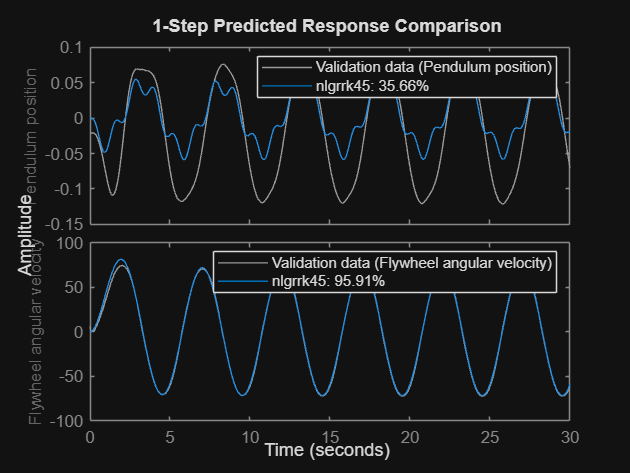

nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_m' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p9)
    y(t) = H(t, u(t), x(t), p1, ..., p9) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 8 free parameter(s) (out of 9).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [-4.118;94.99]%                                         
FPE: 5.563, MSE: 6.529                                                          

Model Properties


ans = 9×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


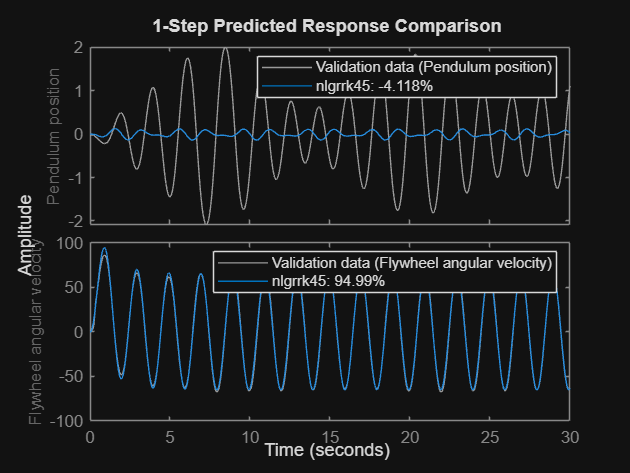

nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_m' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p9)
    y(t) = H(t, u(t), x(t), p1, ..., p9) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 8 free parameter(s) (out of 9).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [28.54;96.97]%                                          
FPE: 0.2715, MSE: 16.26                                                         

Model Properties


ans = 9×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


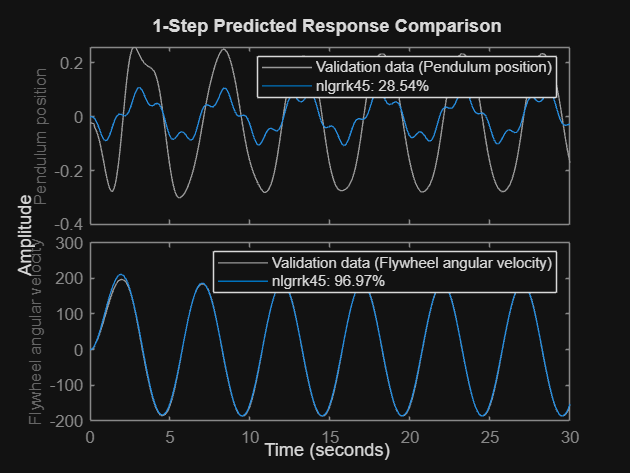

nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_m' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p9)
    y(t) = H(t, u(t), x(t), p1, ..., p9) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 8 free parameter(s) (out of 9).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [-5.38;90.89]%                                          
FPE: 0.002071, MSE: 1.561                                                       

Model Properties


ans = 9×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


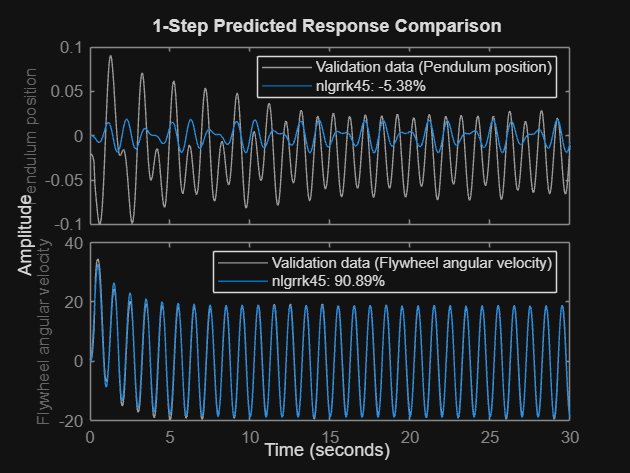

nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_m' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p9)
    y(t) = H(t, u(t), x(t), p1, ..., p9) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 8 free parameter(s) (out of 9).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [-0.4717;89.23]%                                        
FPE: 4.445, MSE: 7.767                                                          

Model Properties


ans = 9×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


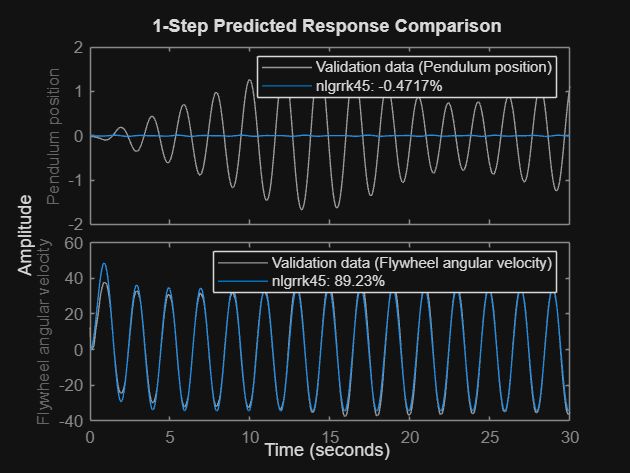


for i = 1:5
    if i==1
        y = D06_05_h05_Ef_As03H02_R01.data(:,2:3);
        u = D06_05_h05_Ef_As03H02_R01.data(:,5);
    elseif i==2
        y = D06_05_h05_Ef_As05H05_R01.data(:,2:3);
        u = D06_05_h05_Ef_As05H05_R01.data(:,5);
    elseif i==3
        y = D06_05_h05_Ef_As07H02_R01.data(:,2:3);
        u = D06_05_h05_Ef_As07H02_R01.data(:,5);
    elseif i==4
        y = D06_05_h05_Ef_As03H10_R01.data(:,2:3);
        u = D06_05_h05_Ef_As03H10_R01.data(:,5);
    else
        y = D06_05_h05_Ef_As03H05_R01.data(:,2:3);
        u = D06_05_h05_Ef_As03H05_R01.data(:,5);
    end
    
    z = iddata(y, u, 0.05, 'Name', 'Pendulum');
    z.OutputName = {'Pendulum position','Flywheel angular velocity'};
    z.OutputUnit = {'rad','rad/s'};
    z.InputName = {'Control Signal'};
    z.Tstart = 0;
    z.TimeUnit = 's';
    
    % nlgrrk45 = pem(z,nlgrrk45, opt)
    nlgrrk45 = nlgreyest(z,nlgrrk45, opt)

    nlgrrk45.Parameters
    figure(i),clf;
        compare(z, nlgrrk45, 1, ...
        compareOptions('InitialCondition', 'model'));
end